# Figure composite Acoustic Group 4 Male calls

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
BoxPath = '/Users/elie/Box';
Path2Paper = fullfile(BoxPath, 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'CallType','MicAudioGood', 'BatID','MPS_mic', 'MPS_mic_wf', 'MPS_mic_wt')
% load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood','TmicAll7');
load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4');
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'MicFileNum', 'MicFileSampleID', 'OnSetOffsetSample', 'CallDate','Q1Mic_mean','Q3Mic_mean');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
load(fullfile(LocalDataDir, 'DeafBats_PCA_MaleAcGroup4.mat'), 'Score_M')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_MaleAcGroup4.mat'), 'NPC_opt_M', 'PC_DF_males', 'EigenVec_DFA_M', 'MPS_mic_wf', 'IndWf', 'MPS_mic_wt')

% Get the color vector ready for BatName, Sex and Deafness
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
Path2RecordingTable = fullfile(BoxPath,'JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end
    
end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

First restrict the MPS spectral frequency to 3 cycles/kHz and normalized all MPS

addpath(genpath('/Users/elie/Documents/CODE/GitHub/umapDistribution'))
IndWf = (MPS_mic_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = sum(MicAudioGood01);
MPS_mic_norm = cell(1,NVoc);
MPS_mic_focus = cell(1,NVoc);
MPS_mic_mean = reshape(mean(MPS_mic(MicAudioGood01,:), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
IndMicAudioGood = find(MicAudioGood01);
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS_mic(vv,:)',length(MPS_mic_wf), length(MPS_mic_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_mic_norm{nn} = reshape(MPS_local./MPS_mic_mean(IndWf,:), numel(MPS_local),1);
    MPS_mic_focus{nn} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_mic_norm = [MPS_mic_norm{:}]';
MPS_mic_focus = [MPS_mic_focus{:}]';

Obtain projection values of calls in DF1 space (cannonical values)

Canon = (Score_M(:,1:NPC_opt_M) - repmat(mean(Score_M(:,1:NPC_opt_M)),size(Score_M,1),1)) * EigenVec_DFA_M(:,1);

Identify 4 examples of calls with extreme values of DF1 for Hearing and Deaf Males and 1 example of average DF1 value for each bat

MicAudioGoodInd = find(MicAudioGood);
NumEx = 6;
MicAudioGoodInd4 = MicAudioGoodInd(logical((TmicAll4==4) .* contains(SexDeaf(MicAudioGoodInd), 'M')));
IndHMLowDF1 = MicAudioGoodInd4(logical((Canon(:,1)<-5.5) .* strcmp(SexDeaf(MicAudioGoodInd4), 'HM')));
IndDMHighDF1 = MicAudioGoodInd4(logical((Canon(:,1)>8.5) .* strcmp(SexDeaf(MicAudioGoodInd4), 'DM')));
Mean_HMDF1 = mean(Canon(strcmp(SexDeaf(MicAudioGoodInd4), 'HM')),1);
Mean_DMDF1 = mean(Canon(strcmp(SexDeaf(MicAudioGoodInd4), 'DM')),1);
AbsDiffHM = abs(Canon-Mean_HMDF1);
AbsDiffDM = abs(Canon-Mean_DMDF1);
IndHMMeanDF1 = MicAudioGoodInd4(logical(AbsDiffHM<(10*min(AbsDiffHM(AbsDiffHM>0)))));
IndDMMeanDF1 = MicAudioGoodInd4(logical(AbsDiffDM<(10*min(AbsDiffDM(AbsDiffDM>0)))));

RandInd0_DM = randperm(length(IndDMHighDF1));
RandInd0_HM = randperm(length(IndHMLowDF1));
BatID_DM_Examples = BatID(IndDMHighDF1(RandInd0_DM));
BatID_HM_Examples = BatID(IndHMLowDF1(RandInd0_HM));
% Select Indices that correspond to two extreme examples per bat and one
% mean example
BatID_DM = unique(BatID_DM_Examples);
BatID_HM = unique(BatID_HM_Examples);
RandInd_DM = nan(NumEx,1);
RandInd_HM = RandInd_DM;
for bb=1:length(BatID_DM)
    II = find(contains(BatID_DM_Examples,BatID_DM{bb}),2);
    RandInd_DM((bb*3-2) : bb*3-1) = RandInd0_DM(II);
    RandInd_DM(bb*3) = find(contains(BatID(IndDMMeanDF1), BatID_DM{bb}),1);
    II = find(contains(BatID_HM_Examples,BatID_HM{bb}),2);
    RandInd_HM((bb*3-2) : bb*3-1) = RandInd0_HM(II);
    RandInd_HM(bb*3) = find(contains(BatID(IndHMMeanDF1), BatID_HM{bb}),1,"last");
end
    
ExampleHM.Spectro = cell(NumEx,1);
ExampleHM.Fo = cell(NumEx,1);
ExampleHM.To = cell(NumEx,1);
ExampleHM.Sound = cell(NumEx,1);
ExampleHM.Q1MicMean = nan(NumEx,1);
ExampleHM.Q3MicMean = nan(NumEx,1);
ExampleHM.DFA1 = nan(NumEx,1);
ExampleHM.BatID = cell(NumEx,1);
ExampleDM = ExampleHM;


for ii=1:NumEx
    fprintf(1, 'Example %d\n',ii)
    % Hearing Males examples (Low DFA1)
    if rem(ii,3)
        IndEx = IndHMLowDF1(RandInd_HM(ii));
    else
        IndEx = IndHMMeanDF1(RandInd_HM(ii));
    end

    ExampleHM.Q1MicMean(ii) = Q1Mic_mean(IndEx);
    ExampleHM.Q3MicMean(ii) = Q3Mic_mean(IndEx);
    ExampleHM.DFA1(ii) = Canon(MicAudioGoodInd4==IndEx);
    WhoFile = dir(fullfile(BaseDataDir, ['20' num2str(CallDate(IndEx))], 'audiologgers', sprintf('DeSa_%s_*_%d_%d*200.pdf', num2str(CallDate(IndEx)),  MicFileNum(IndEx), MicFileSampleID(IndEx))));
     Ind_ = strfind(WhoFile.name, '_');
    SetNum = WhoFile.name((Ind_(7)+1):(Ind_(8)-1));
    ExpTime = WhoFile.name((Ind_(2)+1):(Ind_(3)-1));
    DataFilename = dir(fullfile(BaseDataDir, ['20' num2str(CallDate(IndEx))], 'audiologgers', sprintf('%d_*_VocExtractData%s_200.mat', CallDate(IndEx), SetNum)));
    DataFile = load(fullfile(DataFilename.folder, DataFilename.name));
    if any(cellfun(@isempty,DataFile.BioSoundFilenames(:,2)))
        IndBS = find(~cellfun(@isempty,DataFile.BioSoundFilenames(:,2)));
        CallsInd = IndBS(contains(DataFile.BioSoundFilenames(IndBS,2), sprintf('DeSa_%s_%s_voc_%d_%d', num2str(CallDate(IndEx)), ExpTime,  MicFileNum(IndEx), MicFileSampleID(IndEx))));
    else
        CallsInd = find(contains(DataFile.BioSoundFilenames(:,2), sprintf('DeSa_%s_%s_voc_%d_%d', num2str(CallDate(IndEx)), ExpTime,  MicFileNum(IndEx), MicFileSampleID(IndEx))));
    end
    
    for vv=1:length(CallsInd)
        if any(DataFile.BioSoundCalls{CallsInd(vv),1}.MeanQ1t == Q1Mic_mean(IndEx))
            CallInd = CallsInd(vv);
            break
        end
    end
    [~,Name,~] = fileparts(DataFile.BioSoundFilenames{CallInd,2});
    BatInd = strfind(Name,'Bat');
    ExampleHM.BatID{ii} = Name(BatInd+(3:7));
                
    if isfield(DataFile.BioSoundCalls{CallInd,1}, 'spectro_elmts')
        elmt = find(DataFile.BioSoundCalls{CallInd,1}.MeanQ1t == Q1Mic_mean(IndEx));
        ExampleHM.Spectro{ii} = DataFile.BioSoundCalls{CallInd,1}.spectro_elmts{elmt};
        ExampleHM.Fo{ii} = DataFile.BioSoundCalls{CallInd,1}.fo_elmts{elmt};
        ExampleHM.To{ii} = DataFile.BioSoundCalls{CallInd,1}.to_elmts{elmt};
        ExampleHM.Sound{ii} = DataFile.BioSoundCalls{CallInd,1}.sound(DataFile.BioSoundCalls{CallInd,1}.OnOffSets_elmts(elmt,1):DataFile.BioSoundCalls{CallInd,1}.OnOffSets_elmts(elmt,2));
    else
        elmt=1;
        ExampleHM.Spectro{ii} = DataFile.BioSoundCalls{CallInd,1}.spectro;
        ExampleHM.Fo{ii} = DataFile.BioSoundCalls{CallInd,1}.fo;
        ExampleHM.To{ii} = DataFile.BioSoundCalls{CallInd,1}.to;
        ExampleHM.Sound{ii} = DataFile.BioSoundCalls{CallInd,1}.sound;
    end
    
    % Deaf males examples (high DFA1)
    if rem(ii,3)
        IndEx = IndDMHighDF1(RandInd_DM(ii));
    else
        IndEx = IndDMMeanDF1(RandInd_DM(ii));
    end
    ExampleDM.Q1MicMean(ii) = Q1Mic_mean(IndEx);
    ExampleDM.Q3MicMean(ii) = Q3Mic_mean(IndEx);
    ExampleDM.DFA1(ii) = Canon(MicAudioGoodInd4==IndEx);
    WhoFile = dir(fullfile(BaseDataDir, ['20' num2str(CallDate(IndEx))], 'audiologgers', sprintf('DeSa_%s_*_%d_%d*200.pdf', num2str(CallDate(IndEx)),  MicFileNum(IndEx), MicFileSampleID(IndEx))));
    Ind_ = strfind(WhoFile.name, '_');
    SetNum = WhoFile.name((Ind_(7)+1):(Ind_(8)-1));
    ExpTime = WhoFile.name((Ind_(2)+1):(Ind_(3)-1));
    DataFilename = dir(fullfile(BaseDataDir, ['20' num2str(CallDate(IndEx))], 'audiologgers', sprintf('%d_*_VocExtractData%s_200.mat', CallDate(IndEx), SetNum)));
    DataFile = load(fullfile(DataFilename.folder, DataFilename.name));
    if any(cellfun(@isempty,DataFile.BioSoundFilenames(:,2)))
        IndBS = find(~cellfun(@isempty,DataFile.BioSoundFilenames(:,2)));
        CallsInd = IndBS(contains(DataFile.BioSoundFilenames(IndBS,2), sprintf('DeSa_%s_%s_voc_%d_%d', num2str(CallDate(IndEx)), ExpTime,  MicFileNum(IndEx), MicFileSampleID(IndEx))));
    else
        CallsInd = find(contains(DataFile.BioSoundFilenames(:,2), sprintf('DeSa_%s_%s_voc_%d_%d', num2str(CallDate(IndEx)), ExpTime,  MicFileNum(IndEx), MicFileSampleID(IndEx))));
    end
    
    for vv=1:length(CallsInd)
        if any(DataFile.BioSoundCalls{CallsInd(vv),1}.MeanQ1t == Q1Mic_mean(IndEx))
            CallInd = CallsInd(vv);
            break
        end
    end
    [~,Name,~] = fileparts(DataFile.BioSoundFilenames{CallInd,2});
    BatInd = strfind(Name,'Bat');
    ExampleDM.BatID{ii} = Name(BatInd+(3:7));
                
    if isfield(DataFile.BioSoundCalls{CallInd,1}, 'spectro_elmts')
        elmt = find(DataFile.BioSoundCalls{CallInd,1}.MeanQ1t == Q1Mic_mean(IndEx));
        ExampleDM.Spectro{ii} = DataFile.BioSoundCalls{CallInd,1}.spectro_elmts{elmt};
        ExampleDM.Fo{ii} = DataFile.BioSoundCalls{CallInd,1}.fo_elmts{elmt};
        ExampleDM.To{ii} = DataFile.BioSoundCalls{CallInd,1}.to_elmts{elmt};
        CallType = DataFile.ManualCallType{CallInd}{elmt};
        ExampleDM.Sound{ii} = DataFile.BioSoundCalls{CallInd,1}.sound(DataFile.BioSoundCalls{CallInd,1}.OnOffSets_elmts(elmt,1):DataFile.BioSoundCalls{CallInd,1}.OnOffSets_elmts(elmt,2));
    else
        elmt=1;
        ExampleDM.Spectro{ii} = DataFile.BioSoundCalls{CallInd,1}.spectro;
        ExampleDM.Fo{ii} = DataFile.BioSoundCalls{CallInd,1}.fo;
        ExampleDM.To{ii} = DataFile.BioSoundCalls{CallInd,1}.to;
        CallType = DataFile.ManualCallType{CallInd}{elmt};
        ExampleDM.Sound{ii} = DataFile.BioSoundCalls{CallInd,1}.sound;
    end
end

Example 1
Example 2
Example 3
Example 4
Example 5
Example 6


save(fullfile(LocalDataDir, 'Data4_Figure2_DeafBats_MaleGroup4.mat'), 'ExampleDM','ExampleHM','RandInd_DM','RandInd_HM');

Figure!

Fig1=figure(1);
clf
set(gcf,'Visible','on')
T=tiledlayout(12,20,'TileSpacing','compact');

% The positive direction of the DF1 axis in the MPS space
N=nexttile(1,[4,3]);
[CB1,Im1,~]=plot_mps(PC_DF_males, MPS_mic_wf(IndWf), MPS_mic_wt, 60, nan, 0, [0 max(MPS_mic_wf(IndWf)*10^3)], [-150 150]);
% title('DFA1 in the MPS space positive values')
Cmap = flip([ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)]);
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
xlabel('')
xticklabels('')
yticklabels('')
ylabel('')
N.FontSize = 8;

% The negative direction of the DF1 axis in the MPS space
N=nexttile(161,[4,3]);
[CB3, Im3,~]=plot_mps(-PC_DF_males, MPS_mic_wf(IndWf), MPS_mic_wt, 60, nan, 0, [0 max(MPS_mic_wf(IndWf)*10^3)], [-150 150]);
% title('DFA1 in the MPS space positive values')
Cmap = flip([ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)]);
colormap(Cmap)
caxis([-2 2].*10^-2)
N.FontSize = 8;

% The average MPS for male calls in cat5
N=nexttile(81, [4,3]);
MPS_mic_norm4M = MPS_mic_norm(logical((TmicAll4==4) .* contains(SexDeaf(IndMicAudioGood), 'M')),:);
MPS_mic_norm_5M_mean = reshape(mean(MPS_mic_norm4M, 'omitnan')',length(MPS_mic_wf(IndWf)), length(MPS_mic_wt));
[CB2,Im2,~]=plot_mps(MPS_mic_norm_5M_mean, MPS_mic_wf(IndWf), MPS_mic_wt, 60, nan, 1, [0 max(MPS_mic_wf(IndWf)*10^3)],[-150 150]);
xlabel('')
ylabel('')
xticklabels('')
yticklabels('')
N.FontSize = 8;


% The swarmchart of DF1 values for males color coded with Q3mean
N=nexttile(4, [12,8]);
BatID_MicM4 = BatID(MicAudioGoodInd4);
Q3Mic_mean_MicM4 = Q3Mic_mean(MicAudioGoodInd4);
x=1;
Legend=cell(length(BatName),1);
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(Q3Mic_mean_MicM4,x);
for bb=7:length(BatName)
    BatName_local = num2str(BatName(bb));
    Ind = strcmp(BatID_MicM4, BatName_local);
    hold on
    swarmchart(bb*ones(sum(Ind),1),Canon(Ind,1),30,Colors(Ind,:),'o','filled','MarkerFaceAlpha',0.7,'MarkerEdgeAlpha',0.7)
    SepStr = strsplit(BatSexDeaf{bb});
    if strcmp(SepStr{1}(1), 'H')
        Legend{bb} = ['S' SepStr{2}(1) BatName_local(end)]; 
    else
        Legend{bb} = ['K' SepStr{2}(1) BatName_local(end)]; 
    end
end
ylabel('DFA 1', 'FontSize',8);
ylim([-10 25])
set(gca, 'XTick', 7:10,'XTickLabel', Legend(7:10), 'YTick', [-10 0 10 20],'YTickLabel',[-10 0 10 20], 'XLim', [6 11], 'FontSize',8)
set(gca, 'Color', [0.9 0.9 0.9])
cc=colorbar();
cc.Label.String = 'Third Spectral Quartile (kHz)';
cc.FontSize = 8;
cc.Location = 'north';
N.Colormap = GRAD;
YTL = [0 10000 20000 30000 40000]; % Set which label we want to see in kHz
YT_new = (YTL + Slide)*10^x / ceil((MaxColVal+Slide)*10^x);
set(cc, 'YTickLabel',YTL/10^3,'YTick',YT_new)
cc.Units = 'inches';
cc.Position(4) = 0.1;
cc.Position(2) = cc.Position(2)+0.2;
hold on
hline(0, '--k')
hold on
% indicate the position of examples by short line
line([6.5 6.8],ExampleDM.DFA1(6).*ones(2,1),'Color','k')
hold on
line([6.5 6.8],ExampleDM.DFA1(5).*ones(2,1),'Color','k')
hold on
line([6.5 6.8],ExampleDM.DFA1(4).*ones(2,1),'Color','k')
hold on
line([7.5 7.8],ExampleDM.DFA1(1).*ones(2,1),'Color','k')
hold on
line([7.5 7.8],ExampleDM.DFA1(2).*ones(2,1),'Color','k')
hold on
line([7.5 7.8],ExampleDM.DFA1(3).*ones(2,1),'Color','k')
hold on
line([8.5 8.8],ExampleHM.DFA1(1).*ones(2,1),'Color','k')
hold on
line([8.5 8.8],ExampleHM.DFA1(2).*ones(2,1),'Color','k')
hold on
line([8.5 8.8],ExampleHM.DFA1(3).*ones(2,1),'Color','k')
hold on
line([9.5 9.8],ExampleHM.DFA1(4).*ones(2,1),'Color','k')
hold on
line([9.5 9.8],ExampleHM.DFA1(5).*ones(2,1),'Color','k')
hold on
line([9.5 9.8],ExampleHM.DFA1(6).*ones(2,1),'Color','k')
hold off

% The examples for Deaf Males
DBNOISE =50;
f_low = 0;
F_high = 50000; % This is the max frequency used to calculate the spectrogram and heance to obtain Q1
TileNum = [12 15 18 72 75 78];
fprintf(1, 'Values of examples chosen from left to right and top to bottom, by row\n')

Values of examples chosen from left to right and top to bottom, by row


for ii=1:NumEx
    
    AP=audioplayer(ExampleDM.Sound{ii}./(max(abs(ExampleDM.Sound{ii}))),192000);
    audiowrite(fullfile(Path2Paper,sprintf('AcousticGroup4_Example%d_DeafMaleBat%s.wav',ii, ExampleDM.BatID{ii})),ExampleDM.Sound{ii}./(max(abs(ExampleDM.Sound{ii}))),192000);
    play(AP)
    pause()
    N=nexttile(TileNum(ii), [3,3]);
    logB = ExampleDM.Spectro{ii};
    maxB = max(max(logB));
    minB = maxB-DBNOISE;
    IM=imagesc(ExampleDM.To{ii}*1000,ExampleDM.Fo{ii},logB);          % to is in seconds
    axis xy;
    caxis('manual');
    caxis([minB maxB]);
    cmap = spec_cmap();
    colormap(IM.Parent, cmap);
    v_axis = axis;
    v_axis(3)=f_low;
    v_axis(4)=F_high;
    axis(v_axis);
%     xlabel('time (ms)')
%     ylabel('Frequency');
%     set(N,'YTick',0:25000:F_high,'YTickLabel',0:25:F_high/10^3)
    set(N,'YTick',[],'YTickLabel',{})
%     title(sprintf('KM%s %.1f', ExampleDM.BatID{ii}(end), ExampleDM.DFA1(ii)), 'FontSize',9)
    fprintf(1,'Ex%d KM%s DFA=%.1f  Q3=%.1f\n', ii, ExampleDM.BatID{ii}(end), ExampleDM.DFA1(ii), ExampleDM.Q3MicMean(ii))
    hold on
    L=hline(ExampleDM.Q3MicMean(ii), 'k--');
    L.LineWidth=2;
    N.FontSize = 8;
    hold off
%     N=nexttile(TileNum(ii)+3, [3 1]);
%     plot(Spect_psd_biosound{IndDMHighDF1(RandInd(ii))}, Spect_psdf_biosound{IndDMHighDF1(RandInd(ii))},'LineWidth',2)
%     ylim([0 20000])
%     xlabel('Power')
%     set(N,'YTick',[],'YTickLabel',{})
%     ylabel('Frequency')
end

Ex1 KM3 DFA=13.1  Q3=28000.9
Ex2 KM3 DFA=11.2  Q3=26751.8
Ex3 KM3 DFA=4.4  Q3=21652.5
Ex4 KM1 DFA=9.0  Q3=25854.1
Ex5 KM1 DFA=9.1  Q3=22826.9
Ex6 KM1 DFA=4.3  Q3=21040.2



% The examples for Hearing Males
TileNum = [132 135 138 192 195 198];
for ii=1:NumEx
    
    AP=audioplayer(ExampleHM.Sound{ii}./(max(abs(ExampleHM.Sound{ii}))),192000);
    audiowrite(fullfile(Path2Paper,sprintf('AcousticGroup4_Example%d_HearingMaleBat%s.wav',ii, ExampleHM.BatID{ii})),ExampleHM.Sound{ii}./(max(abs(ExampleHM.Sound{ii}))),192000);
    play(AP)
    pause()
    N=nexttile(TileNum(ii), [3,3]);
    logB = ExampleHM.Spectro{ii};
    maxB = max(max(logB));
    minB = maxB-DBNOISE;
    IM=imagesc(ExampleHM.To{ii}*1000,ExampleHM.Fo{ii},logB);          % to is in seconds
    axis xy;
    caxis('manual');
    caxis([minB maxB]);
    cmap = spec_cmap();
    colormap(IM.Parent, cmap);
    v_axis = axis;
    v_axis(3)=f_low;
    v_axis(4)=F_high;
    axis(v_axis);
    if ii>3
        xlabel('time (ms)');
    end
    if ii==4
        ylabel('Frequency (kHz)', 'FontSize',8);
        set(N,'YTick',0:25000:F_high,'YTickLabel',0:25:F_high/10^3)
    else
        set(N,'YTick',[],'YTickLabel',{})
    end
    hold on
    L=hline(ExampleHM.Q3MicMean(ii), 'k--');
    L.LineWidth=2;
    N.FontSize = 8;
    hold off
    fprintf(1,'Ex%d SM%s DFA=%.1f  Q3=%.1f\n', ii, ExampleHM.BatID{ii}(end),ExampleHM.DFA1(ii), ExampleHM.Q3MicMean(ii))
%     title(sprintf('SM%s %.1f', ExampleHM.BatID{ii}(end),ExampleHM.DFA1(ii)), 'FontSize',9)
%     N= nexttile(TileNum(ii)+3, [3 1]);
%     plot(Spect_psd_biosound{IndHMLowDF1(RandInd(ii))}, Spect_psdf_biosound{IndHMLowDF1(RandInd(ii))},'LineWidth',2)
%     ylim([0 20000])
%     xlabel('Power')
%     set(N,'YTick',[],'YTickLabel',{})
%     ylabel('Frequency')
end

Ex1 SM1 DFA=-5.5  Q3=14679.4
Ex2 SM1 DFA=-5.7  Q3=8070.5
Ex3 SM1 DFA=-1.4  Q3=15761.7
Ex4 SM4 DFA=-6.6  Q3=10296.0
Ex5 SM4 DFA=-7.4  Q3=9825.0
Ex6 SM4 DFA=-1.4  Q3=18195.4


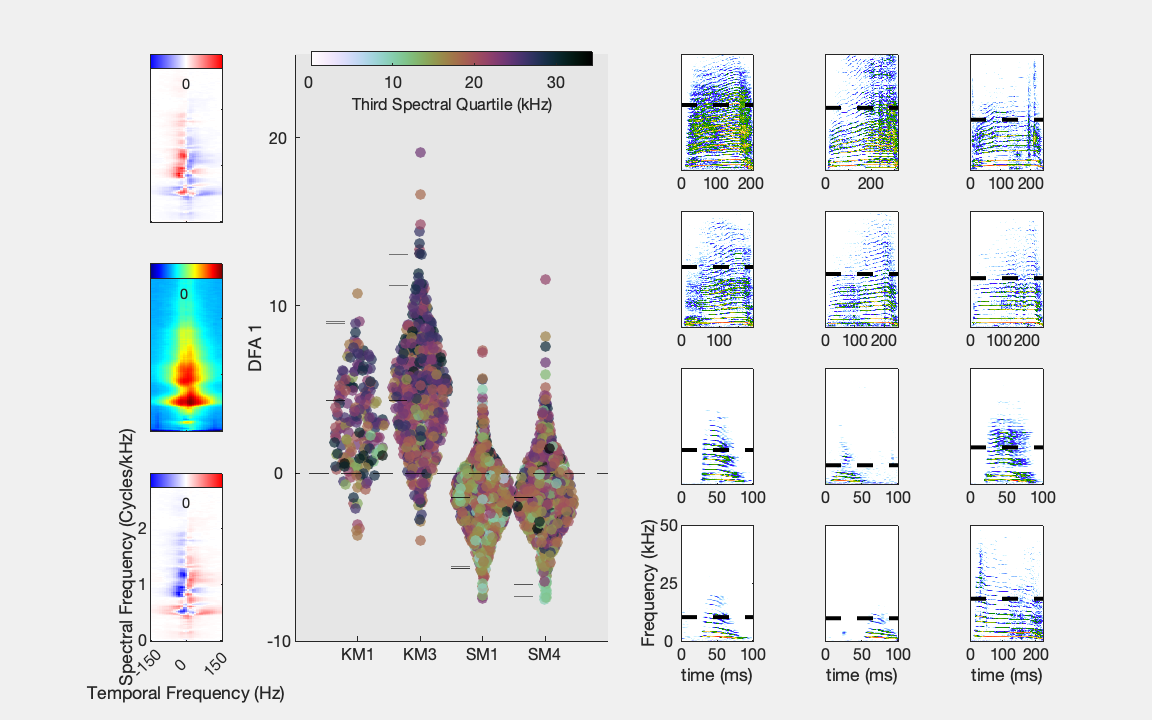

Im1.Parent.Units = 'inches';
CB1.Position(1:3) = Im1.Parent.Position(1:3) + [0 Im1.Parent.Position(4)-0.1 0];
Im2.Parent.Units = 'inches';
CB2.Position(1:3) = Im2.Parent.Position(1:3) + [0 Im2.Parent.Position(4)-0.1 0];
Im3.Parent.Units = 'inches';
CB3.Position(1:3) = Im3.Parent.Position(1:3) + [0 Im3.Parent.Position(4)-0.1 0];

Fig1.PaperOrientation = 'landscape';
Fig1.Units = 'inches';
Fig1.Position(3:4) = [8 5];
Fig1.PaperSize = [8 5];
print(Fig1,fullfile(Path2Paper,['Figure2_MaleCallsGroup4' ...
    '.pdf']),'-dpdf','-fillpage')

Obtain a scatter plot of all calls in the first 2 PCA dimensions with DFA boundary

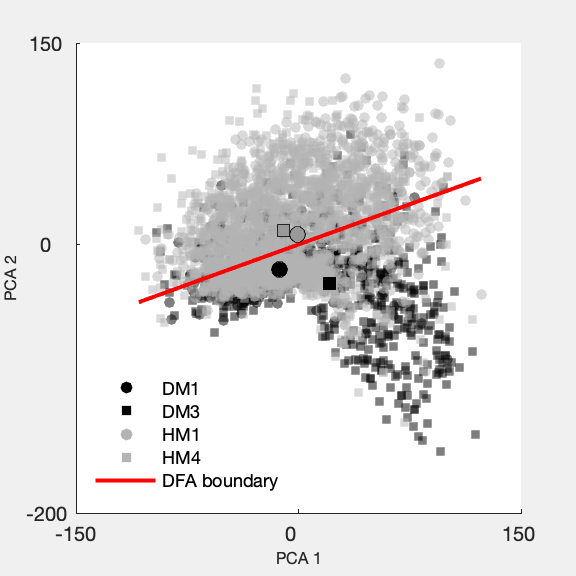

Fig2 = figure(2);
clf
set(gcf,'Visible','on')
Slope = -EigenVec_DFA_M(1,1)/EigenVec_DFA_M(2,1);
Intercept = EigenVec_DFA_M(2,1);
MicAudioGoodInd = find(MicAudioGood);
MicAudioGoodInd4 = MicAudioGoodInd(logical((TmicAll4==4) .* contains(SexDeaf(MicAudioGoodInd), 'M')));
BatID_MicM4 = BatID(MicAudioGoodInd4);
Legend=cell(length(BatName),1);
MKR = {'o', 's', 'o', 's'};
for bb=7:length(BatName)
    BatName_local = num2str(BatName(bb));
    Ind = strcmp(BatID_MicM4, BatName_local);
    hold on
    if contains(BatSexDeaf{bb}, 'D')
        s=scatter(Score_M(Ind,1), Score_M(Ind,2), 30, [0 0 0],MKR{bb-6},"filled");
    else
        s=scatter(Score_M(Ind,1), Score_M(Ind,2), 30, [0.7 0.7 0.7],MKR{bb-6},"filled");
    end
    s.AlphaData = 0.2.*ones(sum(Ind),1);
    s.MarkerFaceAlpha = 'flat';
    SepStr = strsplit(BatSexDeaf{bb});
    if strcmp(SepStr{1}(1), 'H')
        Legend{bb} = ['H' SepStr{2}(1) BatName_local(end)]; 
    else
        Legend{bb} = ['D' SepStr{2}(1) BatName_local(end)]; 
    end
end
ylabel('PCA 2', 'FontSize',8);
xlabel('PCA 1', 'FontSize',8);
X=[min(Score_M(:,1)) max(Score_M(:,1))];
Y = Intercept + Slope.*X;
hold on
line(X,Y,'Color', 'r','LineWidth',2)
Legend{bb+1} = 'DFA boundary';
legend(Legend(7:end), 'AutoUpdate', 'off', 'Location', 'best')
legend('boxoff')
hold on
for bb=7:length(BatName)
    BatName_local = num2str(BatName(bb));
    Ind = strcmp(BatID_MicM4, BatName_local);
    hold on
    MeanBat = mean(Score_M(Ind,1:2));
    if contains(BatSexDeaf{bb}, 'D')
        plot(MeanBat(1), MeanBat(2),'Marker',MKR{bb-6},'MarkerFaceColor',[0 0 0],'MarkerEdgeColor',[0 0 0],'MarkerSize',8, 'LineStyle','none')
    else
        plot(MeanBat(1), MeanBat(2),'Marker',MKR{bb-6},'MarkerFaceColor',[0.6 0.6 0.6],'MarkerEdgeColor',[0 0 0],'MarkerSize',8, 'LineStyle','none')
    end

end
hold off
box off
XLIM = get(gca, 'XLim');
YLIM = get(gca, 'YLim');
set(gca, 'XTick', [XLIM(1) 0 XLIM(2)], 'XTickLabels',[XLIM(1) 0 XLIM(2)],'YTick', [YLIM(1) 0 YLIM(2)], 'YTickLabels',[YLIM(1) 0 YLIM(2)])
Fig2.PaperOrientation = 'landscape';
Fig2.Units = 'inches';
Fig2.Position(3:4) = [4 4];
Fig2.PaperSize = [4 4];
print(Fig2,fullfile(Path2Paper,['Figure_PCAMaleCallsGroup4_DFABoundary' ...
    '.pdf']),'-dpdf','-fillpage')

% ylim([-10 25])
% set(gca, 'XTick', 7:10,'XTickLabel', Legend(7:10), 'YTick', [-10 0 10 20],'YTickLabel',[-10 0 10 20], 'XLim', [6 11], 'FontSize',8)
% set(gca, 'Color', [0.9 0.9 0.9])


function [Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(VARcol,x, MinColVal, MaxColVal)
    % Getting VARZ ready for plotting.
    % If VARcol is always a non-null
    % integer then you can use it directly in cubehelix by specifying x=1
    % otherwise, the function first multiplies VARcol by 10^x to make sure its
    % variability is maximized after ceiling it to an integer
    if nargin<2
        x=3;% here I'm doing *1000 as an example
    end

    if nargin<3
        MinColVal=0;
    end

    if nargin<4
        MaxColVal = max(VARcol);
    end

%     if nargin<5
%         LogToggle=0;
%     end
    % Make sure you don't have nan values
    VARcol = VARcol(~isnan(VARcol));
%     if LogToggle==2
%         VARcol = log2(VARcol);
%     elseif LogToggle==10
%         VARcol = log10(VARcol);
%     end
    

    % Scale your minimum value as 0 or min Val
    Slide = 0;
    if ~MinColVal && sum(VARcol<=0)>0
        Slide = -min(VARcol)+ 10^(-x);
    elseif MinColVal==1
        Slide = -min(VARcol)+ 10^(-x);
    elseif MinColVal
        Slide = -MinColVal+ 10^(-x);
    end

    VARcol_cube = ceil((VARcol+Slide)*10^x);
    %GRAD=cubehelix(max(VARZ_cube));%Note that you can choose the values of...
    ...your gradient by doing cubehelix_view and then specifying the values in...
        ...the function, for instance: GRAD=cubehelix(max(VARZ_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -1.1, 1.5, 0.5, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
    GRAD=cubehelix(ceil((MaxColVal+Slide)*10^x),0.5, -1.5, 1, 1, [1,0]);

    NU = length(VARcol_cube); % this is the number of points you have in your plot
    Colors = nan(NU, size(GRAD,2));
    for jj=1:NU
        Colors(jj,:) = GRAD(VARcol_cube(jj),:); % for each dot you call the line in the gradient of color that correspond to the value in Z
    end
    
% figure()
%     
%     cc=colorbar();
%     colormap(GRAD)
%     set(gca, 'Color', [0.7 0.7 0.7])
%     
%     YTL = get(cc, 'YTickLabel');
%     YTL_new = ceil((MaxColVal+Slide)*10^x) .* str2double(YTL)/10^x - Slide;
%     if LogToggle==2
%         YTL_new = 2.^YTL_new;
%     elseif LogToggle==10
%         YTL_new = 10.^YTL_new;
%     end
%     YTL_new = num2str(round(YTL_new.*10^(x-1))./10^(x-1));
%     set(cc, 'YTickLabel',YTL_new)%here you correct the value of the z axis that you artificially multiplied by 10^x

end


function [CB,Im,MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
    if nargin<4
        DBNOISE=60;
    end

    if nargin<6
        Log=1;
    end

    if nargin<7
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<8
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<5
        CLim = nan;
    end
    if nargin<9
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS = MPS(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    axis xy
    colormap(Im.Parent,'jet');
    CB=colorbar();
    CB.YTick=0;
    CB.YTickLabel=0;
    CB.Units = 'inches';
    CB.Location='north';
    CB.Position(4) = 0.1;
    CB.Position(2) = CB.Position(2) + 0.2;
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(ceil(Wt_local*10^-1))*10^1;
    XTickLabel = [-MaxWt 0 MaxWt];
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    if ~isnan(CLim)
        PlotMPS = gca;
        PlotMPS.CLim = CLim;
    end
end